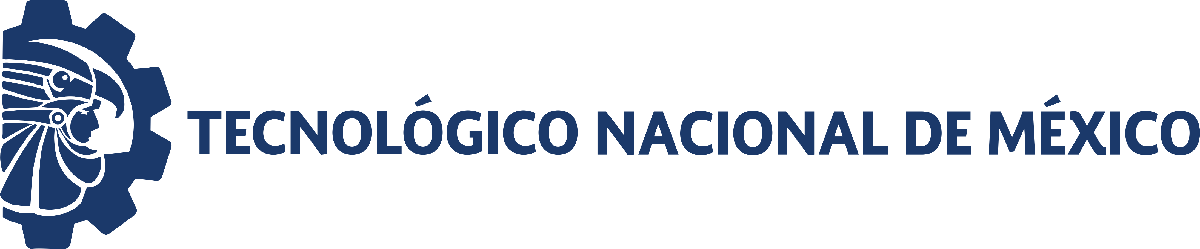                                 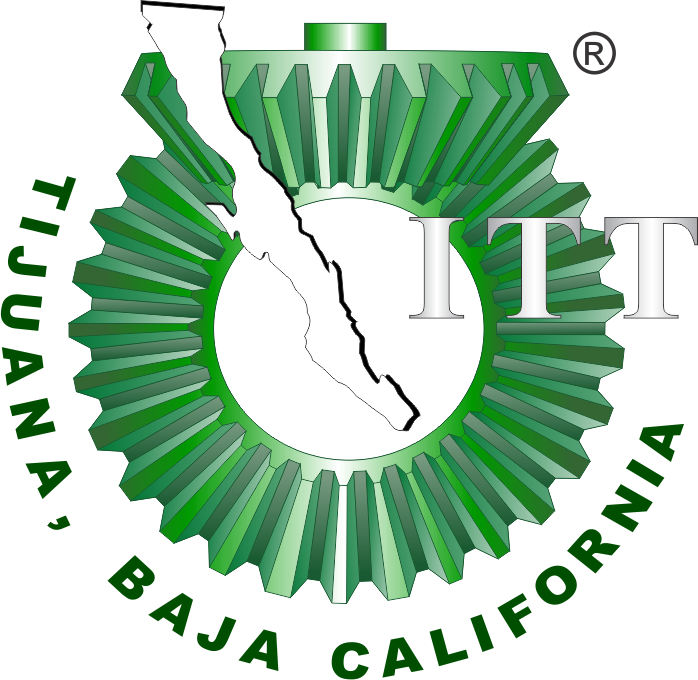

# Práctica 3: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

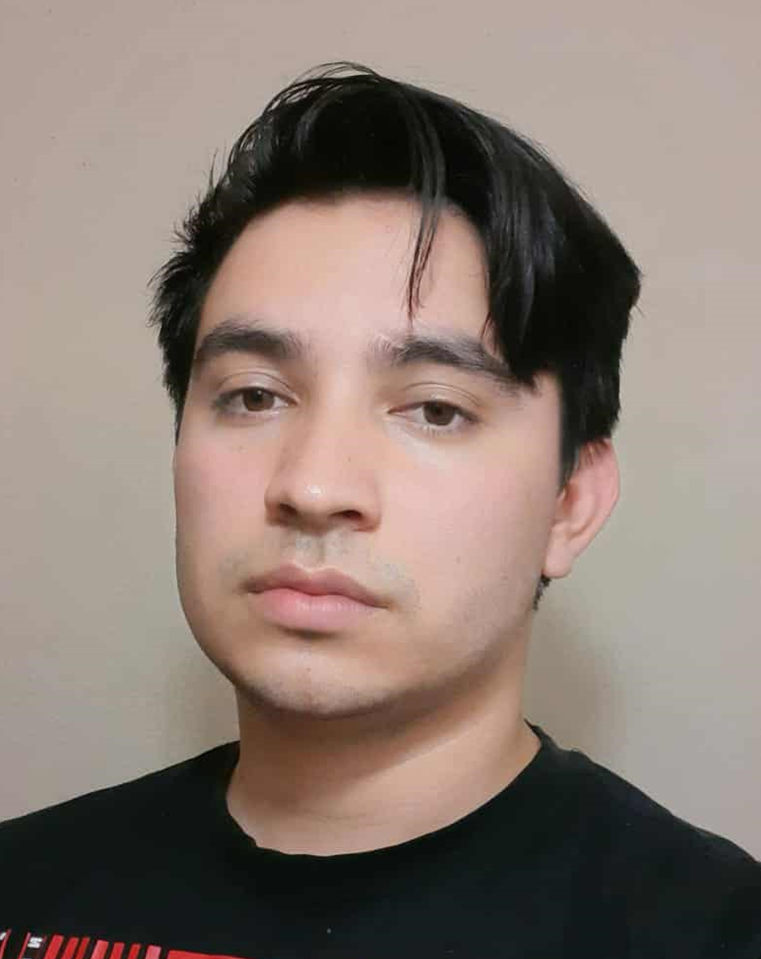

Nombre del alumno: **Erik Rasheed Rendón Carrillo **

Número de control: **20210818**

Correo institucional: **erik.rendonc201@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema_pract3';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
set_param('Sistema_pract3/F(t)','Amplitude','1');
set_param('Sistema_pract3/F(t)','Period','10');
set_param('Sistema_pract3/F(t)','PulseWidth','10');
set_param('Sistema_pract3/F(t)','Phasedelay','1');
x = sim(file,parameters);

Found algebraic loop that contains: 
Sistema_pract3/PID Controller1/Sum/Sum_PI/Sum
Sistema_pract3/PID Controller1/Ideal P Gain/Internal Parameters/Proportional Gain
Sistema_pract3/Fs(t):Tratamiento
Sistema_pract3/Sum1 (algebraic variable)


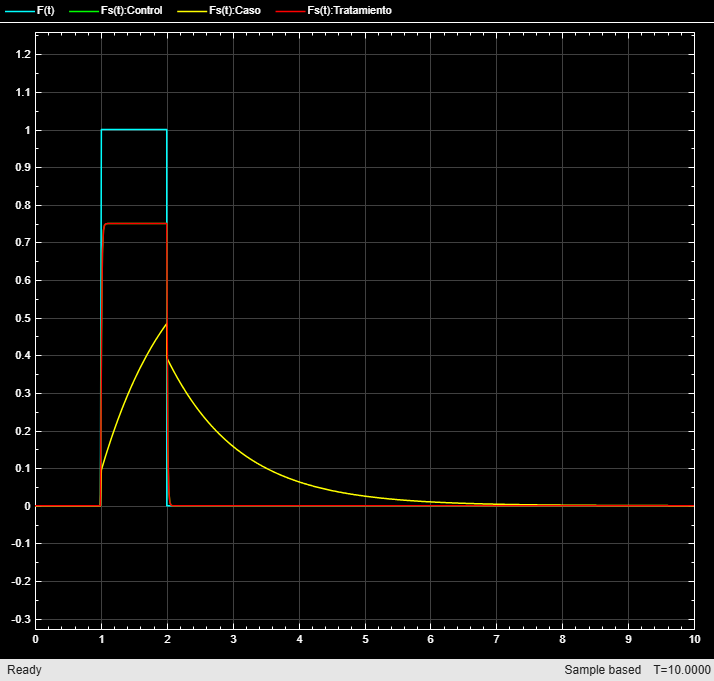

Found algebraic loop that contains: 
Sistema_pract3/PID Controller1/Sum/Sum_PI/Sum
Sistema_pract3/PID Controller1/Ideal P Gain/Internal Parameters/Proportional Gain
Sistema_pract3/Fs(t):Tratamiento
Sistema_pract3/Sum1 (algebraic variable)


x1 = sim(file,parameters);

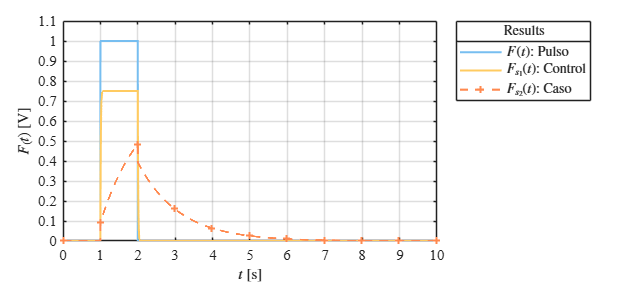

plotsignals(x1.tout, x1.F, x1.Fs1, x1.Fs2, [], 'Lazo abierto');

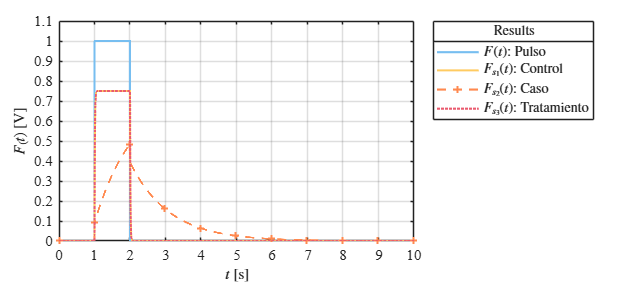

plotsignals(x.tout,x.F,x.Fs1,x.Fs2,x.Fs3,'Lazo Cerrado');

## **Función: Respuesta a las señales**

function plotsignals(tout, F, Fs1, Fs2, Fs3, nombre)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid on; box on;

    mycolors = [119,190,240;
                255,203,97;
                255,137,79;
                234,91,111;
                45,64,89;
                6,66,50]/255;
    colororder(mycolors)

    vars = {F, Fs1, Fs2, Fs3};
    labels = {'$F(t)$: Pulso', ...
              '$F_{s_1}(t)$: Control', ...
              '$F_{s_2}(t)$: Caso', ...
              '$F_{s_3}(t)$: Tratamiento'};
    estilos = {'-', '-', '--+', ':'};

    p = [];
    for i = 1:length(vars)
        if ~isempty(vars{i})
            p(end+1) = plot(tout, vars{i}, estilos{i}, 'LineWidth', 1.5, ...
                'MarkerSize', 5, 'MarkerIndices', 1:1000:length(tout));
        end
    end

    if length(p) >= 5
        set(p(5),'LineWidth',3);
    end

    L = legend(p, labels{1:length(p)}, 'Interpreter', 'Latex', ...
        'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    title(L, 'Results', 'FontSize', 10);

    xlabel('$t$ [s]', 'Interpreter', 'Latex', 'FontSize', 11)
    ylabel('$F_(t)$ [V]', 'Interpreter', 'Latex', 'FontSize', 11)

    xlim([0,10]); xticks(0:1:10);
    ylim([0,1.1]); yticks(0:0.1:1.1);

     exportgraphics(gcf, [nombre '.pdf'], 'ContentType', 'vector');
    exportgraphics(gcf, [nombre '.png'], 'ContentType', 'vector');
end


Yeh